# Example using MODTRAN data to produce an environment file

Data from MODTRAN can be utilised within the qrackling, in the following steps we will take a folder containing MODTRAN data at different elevations and construct a matrix that we can later use as an input to the `Environment` object. This then allows for it to be easily incorporated into satellite pass simulations.

## Existing MODTRAN data

Qrackling provides some example MODTRAN outputs to demonstrate how to make use of this data to build an environment object. These can be found in `Examples\Data\atmospheric transmittance\raw modtran data`. Different files here correspond to different elevations.

Looking at this data, all we really care about is the total transmittance and the wavelengths for which it was computed (the `Waveln` and `combin` columns). We can read these out using `readtable` and then extracting those particular columns.

transmission_table = readtable('Examples\Data\atmospheric transmittance\raw modtran data\Transm_100km_obs_zen_60deg_scan.csv')

transmission_table = 1702×39 table
    Waveln      combin      H2O    umix       O3         trace     N2    H2Ocnt     molec      aercld    HNO3    aercld_1    CO2    CO    CH4    N2O    O2    NH3    NO      NO2        SO2      cloud    F11    F12    CCl3F    CF4    F22    F113    F114    R115    ClONO2    HNO4    CHCl2F    CCl4    N2O5    H2_H2    H2_HE    H2_

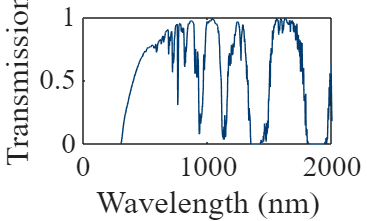

Wavelengths = transmission_table.Waveln;
Transmission = transmission_table.combin;
plot(Wavelengths,Transmission)
xlabel('Wavelength (nm)')
ylabel('Transmission')

## Building up a multi-elevation dataset

If we repeat that process for multiple different elevations, we can build up a 2D dataset of transmission as a function of wavelength and elevation. This is all that is needed to describe atmospheric transmission in Qrackling. Some examples are stored as `.mat` files in `Examples\Data\atmospheric transmittance\transmittance data. Note that these include many different visibilities, so that it is possible to simulate different atmospheric conditions.`

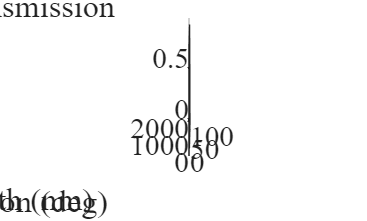

load('Examples\Data\atmospheric transmittance\transmittance data\Elevation_Wavelength_Atmospheric_Transmittance5km.mat',...
    'Elevation','Wavelength','Transmittance');
surf(Elevation,Wavelength,Transmittance)
xlabel('Elevation (deg)')
ylabel('Wavelength (nm)')
zlabel('Transmission')

## Creating an environment

We can then implement this transmission data in an environment object. Usually, these would contain a turbulence model (we will use the default here) and background light data (we will assume it is dark).

Crucially, we need to provide wavelength, heading and elevation dimensions to our dataset. This is to allow background light data, which generally varies with heading, but also allows a more general case of transmission varying with heading.

To do this, we need to repeat our existing transmission data into another dimension, and ensure that it its dimensions line up with the way we expect them to. 

Heading = 0:10:350;
n_Headings = numel(Headings);

%rearrange dimensions so that elevation is the third dimension of the array
%(we want our dimensions to correspond to wavelength, heading, elevation)
Transmittance_rearranged = permute(Transmittance,[1,3,2]);
%then we repeat the data along the 'heading' direction
Transmission_Array = repmat(Transmittance_rearranged,[1,n_Headings,1]);

%create a zero variable to represent spectral radiance (background light)
% this should have dimensions [numel(wavelengths),numel(headings),numel(elevations)]
zero_spectral_radiance_data = zeros(numel(Wavelength),numel(Headings),numel(Elevation));


Env = environment.Environment(Heading,Elevation,Wavelength,zero_spectral_radiance_data,Transmission_Array);

Of course, this method of storage allows different atmospheric transmissions to be implemented in different directions, providing a very general case

## Plotting

Plotting can then be handled by the environment objevt to allow us to view transmission for a varying wavelength. This creates a matlab live figure

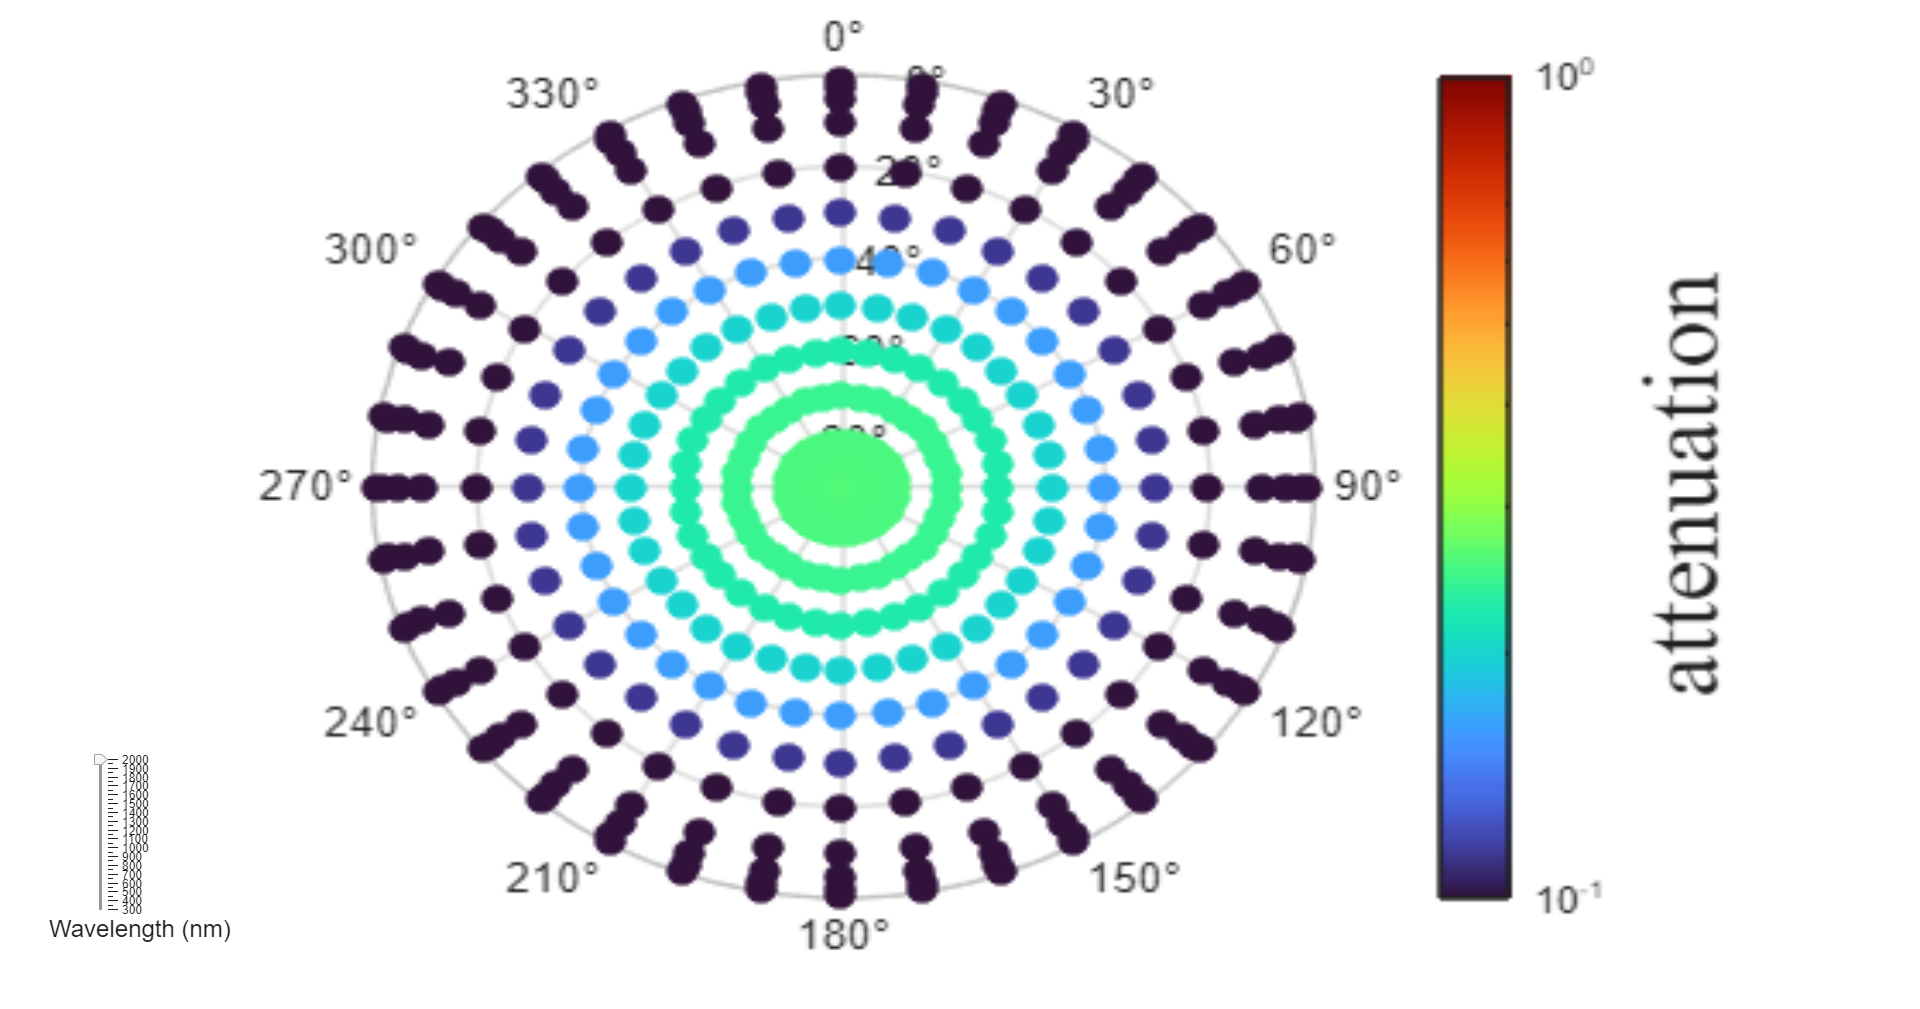

Plot(Env,'attenuation')

## loading other environments

Qrackling provides some default environments which can be loaded easily. These are stored in a folder called `Examples\Data\atmospheric transmittance and implement atmospheric transmittance. Their labels correspond to the atmospheric visibility which they represent.`

Env = environment.Environment.Load('Examples\Data\atmospheric transmittance\Dark Environment 500m.mat')

Env =   Environment with properties:

          wavelengths: [300 301 302 303 304 305 306 307 308 309 310 311 312 313 314 315 316 317 318 319 320 321 322 323 324 325 326 327 328 329 330 331 332 333 334 335 336 337 338 339 340 341 342 343 344 345 346 347 348 349 350 351 … ] (1×1701 double)
             headings: [0 90 180 270]
           elevations: [1 2 5 10 20 30 40 50 60 70 80 90]
     turbulence_model: [1×1 environment.Turbulence_Model]
          attenuation: [1701×4×12 double]
     attenuation_unit: "probability"
    spectral_radiance: [1701×4×12 double]


This low-visiblity example demonstrates high atmospheric attenuation. We can make this easier to see by plotting in dB

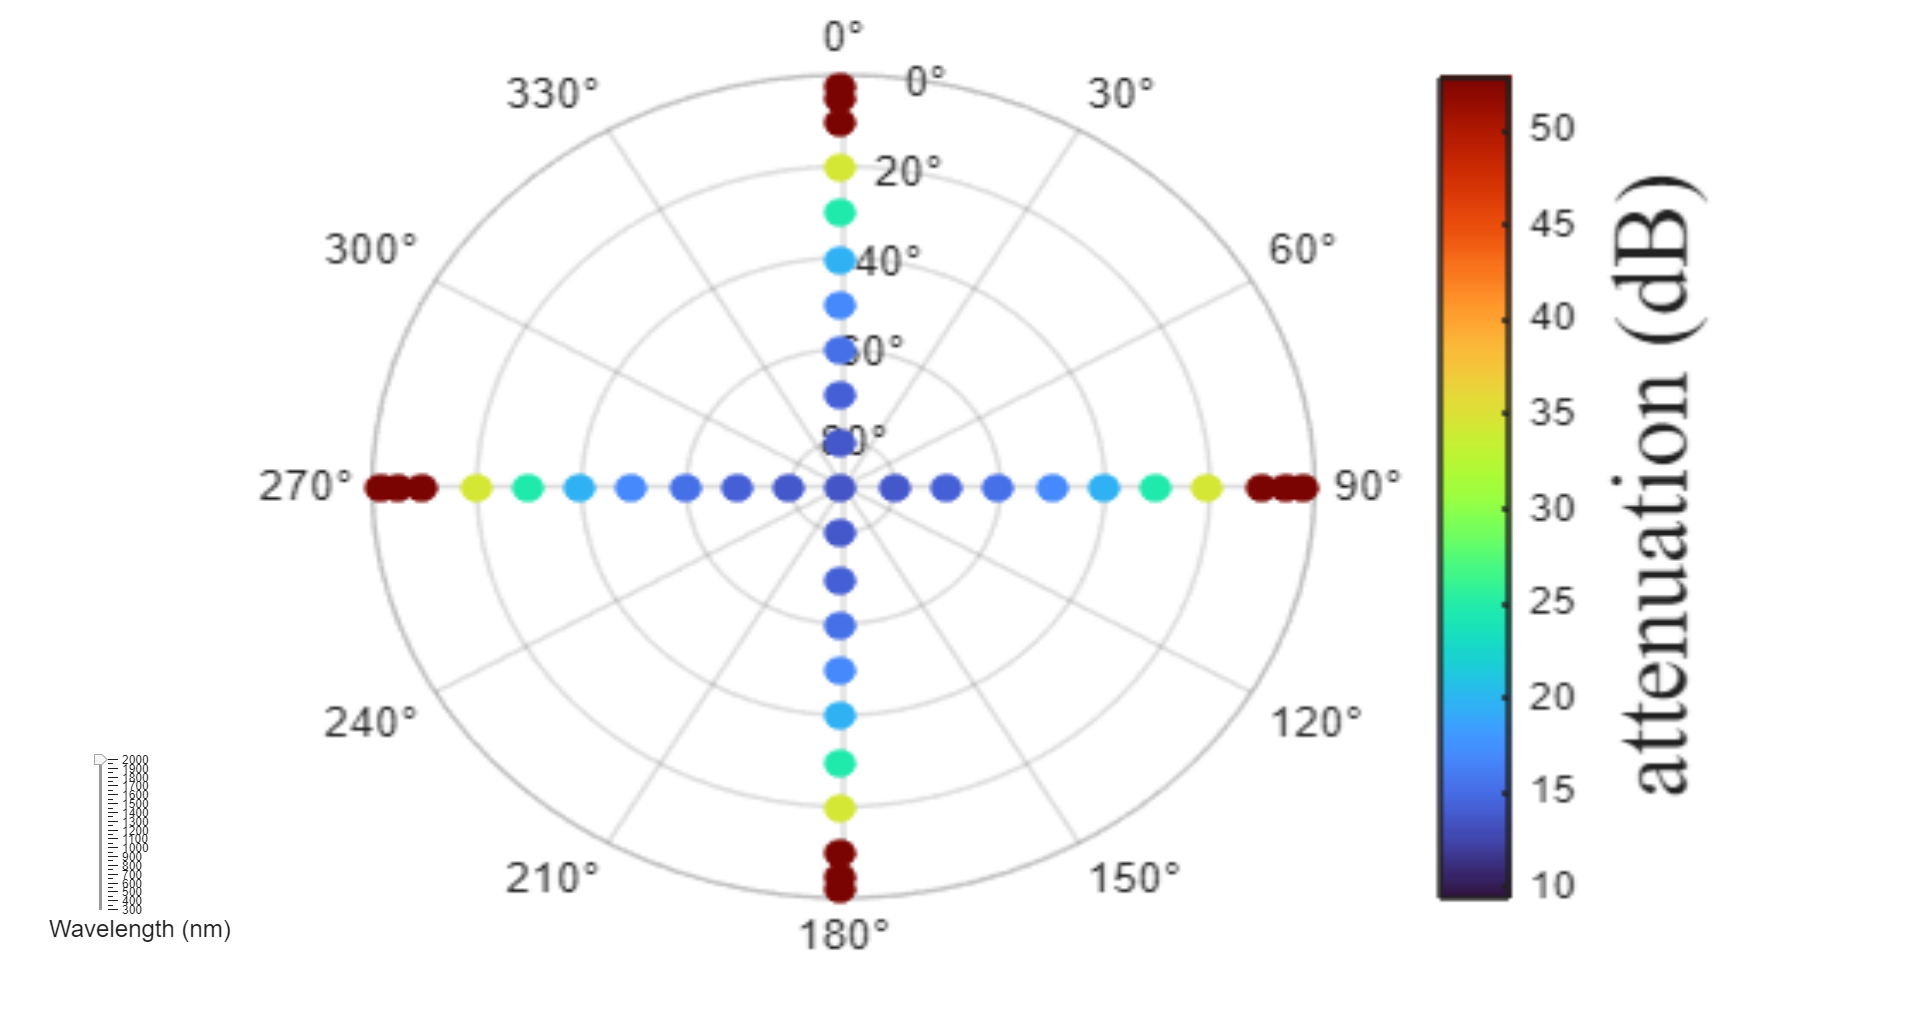

Plot(Env,'attenuation dB')

Note that the lower density of the heading axis is used in all these environment files. Since heading is interpolated against, and does not alter transmission, having a low heading resolution does not change any transmission results. However, if spectral radiance data were included, this would determine the heading resolution,